# Training data calculation (static)

yoshimura code をマイナーチェンジ→genTrainStaticFixed_h.mlxをマイナーチェンジ

- 学習データの入力に過去のライトカーブの平均を追加（平均を取る理由は，推定の時には観測ノイズが乗るため1step前の値だけだとあまり意味を持たない．と考えたから．）

衛星の姿勢と，Obs-Sun-Sat の幾何的な関係からライトカーブを回帰するための学習データをとりあえず作る

- light curveの計算では km ではなく，m で計算をすることに注意．

clc
clear

### add path to use functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得

% create directory
mkdir ../../data/static/


tStart = tic;

### clear the data directory

traindatadir = strcat(curdir, '/../../data/static');
cddir = traindatadir;
cd(cddir);
delete *.csv
cd(curdir);

### flags and constants

TLE = 1;
model = 2; % 1: flatplate, 2: boxWing
nMC = 1; % # of training data
lcModel = 'AS';
fixed = 'random' % "random" or "tleInit" or ""

fixed = 'random'


const = orbitConst;
earthVSOP = vsopConst;

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

% 表面特性の学習. Amos ver.
% CdCs_mat = [0.9, 0.1
%             0.75, 0.25
%             0.6, 0.4
%             0.5, 0.5
%             0.1, 0.9];

% 表面特性の学習等間隔 ver.
CdCs_mat = [0.9, 0.1
            0.7, 0.3
            0.5, 0.5
            0.3, 0.7
            0.1, 0.9];

past_timeSpan = 20; % odeを解く時間とその平均を取るためのtime span


## satellite parameter

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
    sat.rho = sat.Cd;
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.m = 100; % mass, kg
    %   optical parameters at wing (manually...)
    sat.Ca(:,:) = 0.0;
    % sat.Cd(:,:) = 0.7;
    % sat.Cs(:,:) = 0.3;
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
    % sat.rho = sat.Cd;

else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


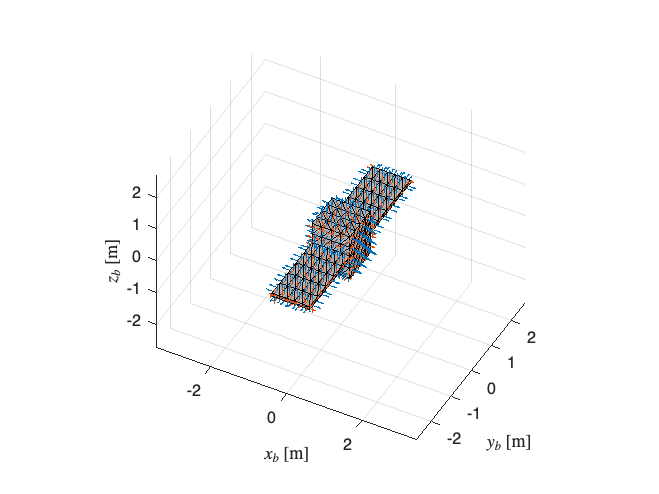

showSC(sat,"Normal","on") % visualize satellite

### initial condition

### orbit

tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}$

% if TLE == 1
%     tle = readTLE('JCSAT2.txt', const);
% else
%     a = 42164.91220781728; % km
%     e = 0.000215800000000; % eccentricity
%     inc = 0.000938987137573; % rad
%     W = 4.918899828139163; % rad
%     w = 0.876621287411436; % rad
%     m = 1.585708419923936; % rad
% 
%     tle.oe = [a e inc W w m];
%     tle.jd = 2.458535992836310e+06;
% end

### satllite & observer & Sun location

とりあえず全ての位置を固定

rng(1, "twister"); % 乱数の再現性

% satellite position
satPos = [0, 0, 0] % sat is origin

satPos =      0     0     0



nSun = 1; % 太陽の位置の数

if strcmp(fixed, "random")
    % observer position
    obsPos = [36000, 0, 0] % 高度36000km 
    obsPos = obsPos .* 10^3; % [m]
    
    sunAzi = pi .* rand(nSun, 1) - pi/2;
    sunEle = acos(1 - 2 .* rand(nSun, 1));
    sunPos = const.AU .* [cos(sunAzi).*sin(sunEle), sin(sunAzi).*sin(sunEle), cos(sunEle)]  % km
    sunPos = sunPos .* 10^3; % [m]
elseif strcmp(fixed, "tleInit")
    % jdHistory = tle.jd + s2day(t_); % time history in Julian day
    % jdHistory = tle.jd;
    % [yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
    % utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
    
    
    % とりあえずべたうちでscjsat.tleの初期位置と合わせてみる -----------
    obsPos = [-2.0005, -3.2290, 0.3506] .* 10^4; % [km]
    obsPos = obsPos .* 10^3; % [m]
    sunPos = [1.3096, -0.6315, -0.2736] .* 10^8; % [km]
    sunPos = sunPos .* 10^3; %[m]
end

obsPos =        36000           0           0


sunPos = 1.0e+08 *

    1.2975   -0.3461   -0.6592


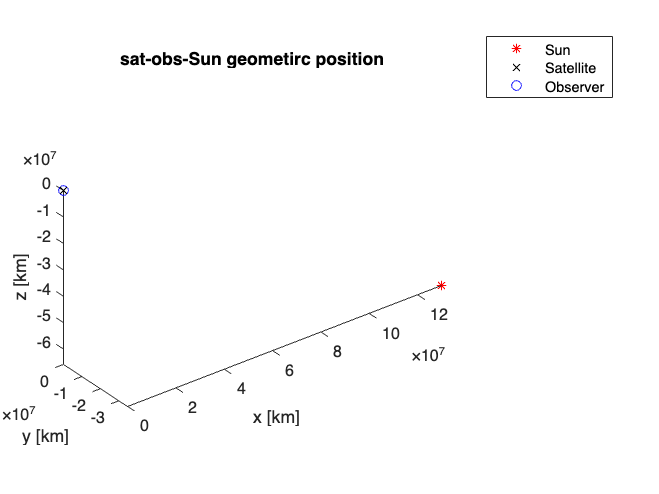



% plot ------
figure
plot3(sunPos(:,1)./10^3, sunPos(:,2)./10^3, sunPos(:,3)./10^3,'r*');
hold on;
plot3(satPos(:,1)./10^3, satPos(:,2)./10^3, satPos(:,3)./10^3, 'kx');
hold on;
plot3(obsPos(:,1)./10^3, obsPos(:,2)./10^3, obsPos(:,3)./10^3, 'bo');
% tmp = gmst(jdHistory(end));
% drawEarth(tmp, 0.6, const);
legend("Sun", "Satellite", "Observer");
xlabel('x [km]'), ylabel('y [km]'), zlabel('z [km]')
title("sat-obs-Sun geometirc position");
axis equal

### satellite attitude

resultDirName = "figs_icosphere"

resultDirName = "figs_icosphere"

dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

savedir = strcat(curdir, "/", dirName);


[v_icoshedron, f_icosahedron] = icosahedron_h();

figname = "icosahedron"

figname = "icosahedron"

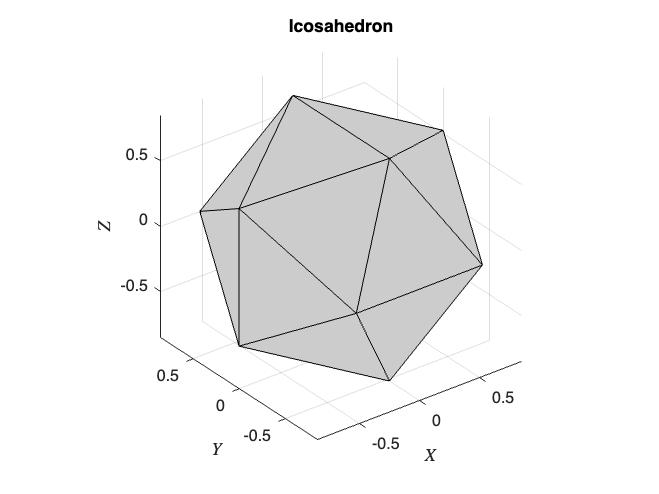

figure;
h = patch('Vertices', v_icoshedron, 'Faces', f_icosahedron, ...
          'FaceColor', '[0.8, 0.8, 0.8]', 'EdgeColor', 'black');
grid on;
view(3)
axis equal;
% xlabel('x'); ylabel('y'); zlabel('z');
title('Icosahedron');
xlabel('$X$', 'Interpreter', 'latex');
ylabel('$Y$', 'Interpreter', 'latex');
zlabel('$Z$', 'Interpreter', 'latex');
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);




[vv, ff] = icosphere(3);
[azi, ele, ~] = cart2sph(vv(:,1), vv(:,2),vv(:,3));
nAzi = length(azi);

% only verticies
figname = "icosphere_onlyVerticies"

figname = "icosphere_onlyVerticies"

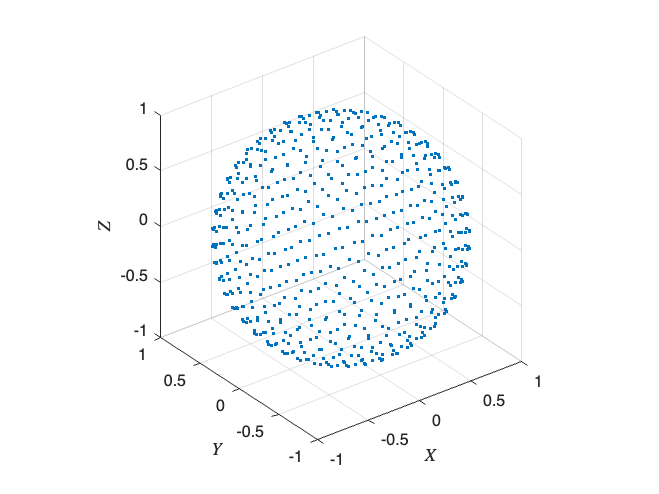

figure
plot3(cos(azi).*cos(ele), sin(azi).*cos(ele), sin(ele),'.'); % km
grid on;
axis equal;
xlabel('$X$', 'Interpreter', 'latex');
ylabel('$Y$', 'Interpreter', 'latex');
zlabel('$Z$', 'Interpreter', 'latex');
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "icosphere"

figname = "icosphere"

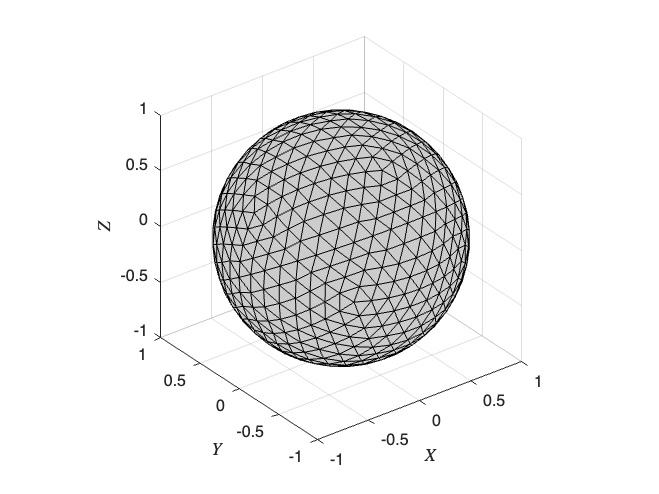

figure;
h = patch('Vertices', vv, 'Faces', ff, ...
          'FaceColor', '[0.8, 0.8, 0.8]', 'EdgeColor', 'black');
grid on;
view(3)
axis equal;
xlabel('$X$', 'Interpreter', 'latex');
ylabel('$Y$', 'Interpreter', 'latex');
zlabel('$Z$', 'Interpreter', 'latex');
% title('Icosphere');
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);




psiStep = deg2rad(60)
psi = 0:psiStep:2*pi-psiStep;
nPsi = length(psi);

qIni = [];
for i = 1:length(azi) % each azimuth and elevationに対してpsiをふる
    tmp = zyz2q(4, azi(i) .* ones(nPsi,1), (pi/2-ele(i)) .* ones(nPsi,1), psi);
    qIni = [qIni
        tmp];
end

wIni = deg2rad([0.1, -0.1, -0.25]); % とりあえず1パターン

nTrain = nSun * length(azi) * length(psi)
patterns_surfaceParameters = size(CdCs_mat, 1)

### generate training data

satPos = repmat(satPos, nTrain, 1);
obsPos = repmat(obsPos, nTrain, 1);
sunPos = repmat(sunPos, nTrain, 1);
% q = repmat(q, nSun, 1);

mApp_pastMean = zeros(nTrain, size(CdCs_mat, 1));
mApp = zeros(nTrain, size(CdCs_mat, 1));

q = zeros(nTrain, 4, size(CdCs_mat, 1));

tstep = 1;
tspan = 0:tstep:past_timeSpan;

options = odeset('RelTol',1e-9,'AbsTol',1e-9);

for i = 1:1:size(CdCs_mat, 1)
    sat.Cd = CdCs_mat(i,1);
    sat.Cs = CdCs_mat(i,2);
    sat.rho = sat.Cd;
    for j = 1:1:size(qIni, 1)
        mApp_tmp = zeros(size(tspan, 2), 1);
        satPos_tmp = satPos(1:size(tspan,2), :);
        obsPos_tmp = obsPos(1:size(tspan,2), :);
        sunPos_tmp = sunPos(1:size(tspan,2), :);

        xIni = [qIni(j,:), wIni];
        [t_, x_] = ode89(@(t,x)eomAtti_h(t,x,sat), tspan, xIni, options); % torque free
        q_tmp = x_(:,1:4);
        w_tmp = x_(:,5:7);
        [mApp_tmp(:, 1), ~] = lc(sat, 4, q_tmp, satPos_tmp, obsPos_tmp, sunPos_tmp, 1, 'AS');
        mApp_pastMean(j,i) = mean(mApp_tmp(1:(end-1), 1));
        mApp(j,i) = mApp_tmp(end,1); % [nTrain, patterns of CdCs]

        q(j,:,i) = q_tmp(end,:); % 一応3次元目で表面特性ごとにわけてるけど，たぶん全部同じ
    end
        % [mApp(:, i), ~] = lc(sat, 4, q, satPos, obsPos, sunPos, 1, 'AS'); % [nTrain, patterns of CdCs]
end

### save data

savedir = strcat(curdir, '/../../data/static/')
for i = 1:1:size(mApp, 2)
    fName = strcat('trainStatic', sprintf('%03d', i), '.csv');
    saveName = strcat(savedir, fName);
    writematrix([mApp(:,i), q(:,:,i), satPos, obsPos, sunPos, mApp_pastMean(:,i)], saveName);
end
% fName = strcat('yTrain', sprintf('%03d', i), '.csv');
% saveName = strcat(savedir, fName);
% writematrix(mApp, saveName);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))